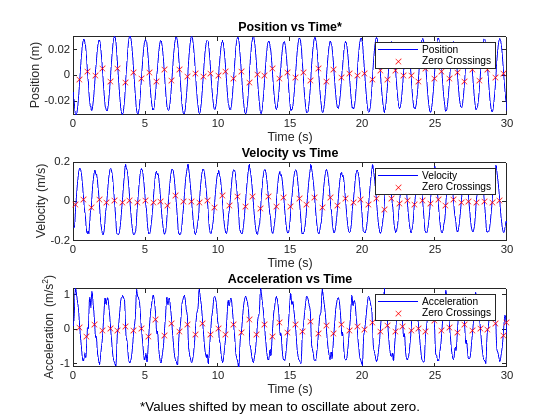


% -----------------------------------------------------------------
% Find Zero-crossing Times for Displacement, Velocity, Acceleration
% -----------------------------------------------------------------

% Identify position zero-crossings
pos_zero_crossings = (shifted_pos(1:end-1) .* shifted_pos(2:end)) < 0;

% Extract the times at which zero-crossings occur
pos_crossing_indices = find(pos_zero_crossings);
pos_crossing_times = times(pos_crossing_indices);

% Identify velocity zero-crossings
vel_zero_crossings = (velocities(1:end-1) .* velocities(2:end)) < 0;

% Extract the times at which zero-crossings occur
vel_crossing_indices = find(vel_zero_crossings);
vel_crossing_times = times(vel_crossing_indices);

% Identify velocity zero-crossings
accel_zero_crossings = (accelerations(1:end-1) .* accelerations(2:end)) < 0;

% Extract the times at which zero-crossings occur
accel_crossing_indices = find(accel_zero_crossings);
accel_crossing_times = times(accel_crossing_indices);

% --------------------------------------------------
% Plot Oscillations with zero-crossings
% --------------------------------------------------

% Subplots for Position, Velocity, Acceleration
figure;

subplot(3, 1, 1);
plot(times, shifted_pos, 'b');  hold on;
plot(pos_crossing_times, shifted_pos(pos_crossing_indices), 'rx');
title('Position vs Time*');  xlabel('Time (s)');  ylabel('Position (m)');
legend({'Position', 'Zero Crossings'});  hold off;

% Subplot 2: Velocity
subplot(3, 1, 2);
plot(times, velocities, 'b');  hold on;
plot(vel_crossing_times, velocities(vel_crossing_indices), 'rx');
title('Velocity vs Time');  xlabel('Time (s)');  ylabel('Velocity (m/s)');
legend({'Velocity', 'Zero Crossings'});  hold off;

% Subplot 3: Acceleration
subplot(3, 1, 3);
plot(times, accelerations, 'b');  hold on;
plot(accel_crossing_times, accelerations(accel_crossing_indices), 'rx');
title('Acceleration vs Time');  xlabel('Time (s)');  ylabel('Acceleration (m/s^2)');
legend({'Acceleration', 'Zero Crossings'});  hold off;

% Add annotation to indicate the asterisk explanation
annotation('textbox', [0.1, 0.01, 0.8, 0.05], 'String', ...
    '*Values shifted by mean to oscillate about zero.', 'EdgeColor', 'none', ...
    'HorizontalAlignment', 'center', 'FontSize', 10);